# Extract 2D Slice ROIs from Mice DKE Maps

## Introduction

This is a MATLAB Live script used to extract information from DKE maps obtained from mice brains at different time points. ROIs drawn in ImageJ are used to set constraints on location of information withing each parameter map. While the images themselves are 3D, the ROIs drawn in MATLAB are 2D on any given slice, so a 2D approach will be used to extract these ROIs.

In this code section, MATLAB is being prepared to utilize paths 

## Define Constrains

Constrains have to be defined to set limits on metric maps for analysis.

### Directories

A study directory needs to be defined for the analysis, this is obvious enough. The directory needs to be setup such that it contains two sub-directories titles ***Images*** and ***ROIs. ***Look at the image below for reference.

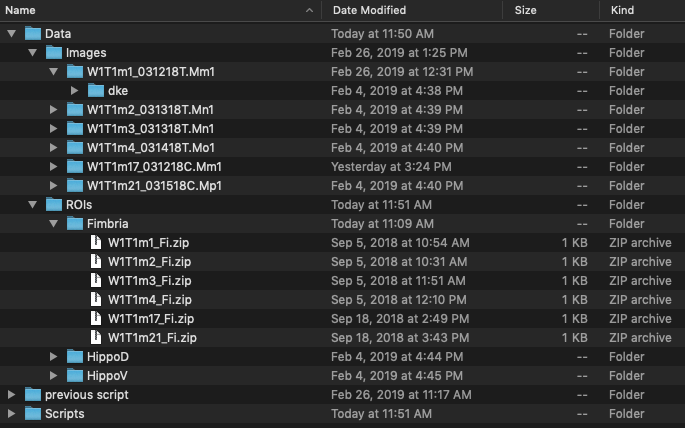

The *studyPath* here is called ***Data, ***and it contains the two subfolders specified above. The ROIs folder should be organized to contain more subfolders denoting categorical locations of ROI, which in turn will hold the ImageJ ROI.zip **per subject**. The Images folder will contain ***Subjects/dke/ ***holding all DKE maps, and should be organized the way shown in the image above. When the select directory box opens, please select the main studyPath parent folder containing both Images and ROIs folder - in this exampe, it is the Data folder.

%   Define study path here
imagePath = '/Users/sid/Documents/Projects/Fatima-Mouse/Data/Images';
%   Define ROI path here
roiPath = '/Users/sid/Documents/Projects/Fatima-Mouse/Data/ROIs';
%   Define analysis output path here
outPath = '/Users/sid/Documents/Projects/Fatima-Mouse/Output';
addpath('ReadImageJROI/');

### Map Ranges

Different maps have different ranges typically defined by a pair of numbers denoting minimum and maximum. There are three main types of metrics being analysed:

- Diffusion

- Kurtosis

- Fractional Anisotropy

These constrains have to specified such that they exclude information such as CSF that fall outside the range of analysis. In addtion, also define the metrics that this script should extract.

Drange = [0 1.5];
Krange = [0 3];
Frange = [0 1];
relMetrics = {'dmean','drad','dax','kmean','krad','kax','fa'};

## Create Directory Listings

### Images Folder

Next, we'll create a listing of the entire Images folder to read subject information.

%% Create Subject Listing
imageDir = dir(imagePath);
%   Clean up listing
imageDir = imageDir(~startsWith({imageDir.name},'.'));
for i = 1:length(imageDir)
    subList{i} = imageDir(i).name;
end

%   Clean up dates from subList
for i = 1:length(subList)
    nm = split(subList{i},'_');
    subNames(i) = nm(1);
end

The two variables *subList *anbd *subNames *contain fullpath to subject directories and subject names respectively. These paths and names will guide the script in pulling the correct metrics from the right subject.

### ROIs Folder

Next, do the same on ROIs folder to read categorical location of ROIs.

%% Create ROI Region Listing
roiDir = dir(roiPath);
%   Clean up listing
roiDir = roiDir(~startsWith({roiDir.name},'.'));
for i = 1:length(roiDir)
    roiList{i} = roiDir(i).name;
end

### Create Output Directories

Data analysis should have an output directory to be saved to. This step creates an output directory that will hold all information of statistics and figures.

## Create Output Directory

outExcel = fullfile(outPath,'Excel_Sheets');
outQC =  fullfile(outPath,'QC');
mkdir(outExcel);
mkdir(outQC);

## Run ROI Analysis

With all paths and variables defined, it is time to analyze the information. The code is documented via in-line comments, so please refer to those to understand the procedure.

%% Run ROI Analysis
%   Find every possible ImageJ ROI
allROIs = dir(fullfile(roiPath,'**/*.zip'));
cntA = 0;
for i = 1:length(subNames);
    %   List ROI file names
    metricNames = dir(fullfile(imagePath,subList{i},'dke','*.nii'));
    %   Remove non-metric files
    metricNames = metricNames(contains({metricNames.name},relMetrics));
    %   Open each file
    for j = 1:length(metricNames)
        curName = metricNames(j).name;
        %   Open a metric file
        V = niftiread(fullfile(metricNames(j).folder,metricNames(j).name));
        
        if contains(curName,{'dmean','drad','dax'});
            range = Drange;
        elseif contains(curName,{'kmean','krad','kax'});
            range = Krange;
        else
            range = Frange;
        end
        
        %   Match ROI with subjects name
        idxROI = find(contains({allROIs.name},subNames{i}));
        
        for k = 1:length(idxROI)
            nROI = idxROI(k);
            try
                %   Locate ROI
                [~,roiLoc,~] = fileparts(allROIs(nROI).folder);
                
                %   Open each ROI
                tmpExtract = tempname(roiPath);
                unzip(fullfile(allROIs(nROI).folder,allROIs(nROI).name),...
                    tmpExtract);
                rRegions = dir(fullfile(tmpExtract,'*.roi'));
            catch
                continue
            end
            
            %   Convert every labelled region to a mask and concatenate along 4th
            %   dimension
            for iReg = 1:length(rRegions)
                
                [sROI] = ReadImageJROI(fullfile(rRegions(iReg).folder,...
                    rRegions(iReg).name));
                
                    roiBW = poly2mask(sROI.mnCoordinates(:,1),sROI.mnCoordinates(:,2),...
                        size(V,1),size(V,2));
                    figure,imshowpair(V(:,:,sROI.nPosition),roiBW,'blend')
                    axis image;
            end
                    
                 
                
                
                %%%%%%%%%%%%%%%%%%%%
                fidROI = fopen(fullfile(rRegions(iReg).folder,...
                    rRegions(iReg).name),'r','ieee-be');
                
                %   Create mask from information about nROI
                
                %%%%%%%%%%%%%%%%%%%%
                
                cntA = cntA + 1;    %   Loop counter
                roiMask = lRegions == iReg;
                maskedV = V(roiMask);
                %   Apply ranged filter
                maskedV = maskedV(find(maskedV >= range(1) & maskedV <= range(2)));
                roiMetrics(cntA).subject = subNames{i};
                roiMetrics(cntA).metric = curName;
                
                roiMetrics(cntA).location = roiLoc;
                roiMetrics(cntA).index = cntA;
                roiMetrics(cntA).roi_index = iReg;
                roiMetrics(cntA).roi_title = allROIs(idxROI(k)).name;
                roiMetrics(cntA).area = nnz(roiMask);
                roiMetrics(cntA).mean = mean(maskedV(find(maskedV)));
                roiMetrics(cntA).stdev = std(maskedV(find(maskedV)));
                roiMetrics(cntA).min = min(maskedV(find(maskedV)));
                roiMetrics(cntA).max = max(maskedV(find(maskedV)));
                roiMetrics(cntA).median = median(maskedV(find(maskedV)));
                clear roiMask maskedV
            end
        end
        clear V
    end
end